# Q1

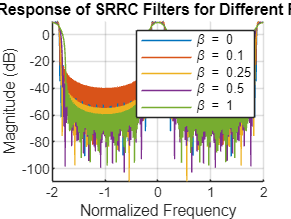

% Define parameters
roll_off_factors = [0, 0.1, 0.25, 0.5, 1]; % Roll-off factors (β)
symbol_rate = 1;  % Symbol rate (normalized to 1)
oversampling_factor = 8; % Oversampling factor (samples per symbol)
filter_span = 10; % Filter span in symbols (must be integer)

% Frequency range for plotting
freq_range = linspace(-2, 2, 1000);

% Initialize figure
figure;
hold on;
grid on;

% Loop through each roll-off factor
for beta = roll_off_factors
    % Design SRRC filter using MATLAB's built-in function
    srrc_filter = rcosdesign(beta, filter_span, oversampling_factor, 'sqrt');
    
    % Calculate frequency response
    [H, f] = freqz(srrc_filter, 1, freq_range, 2 * symbol_rate);
    
    % Plot magnitude response
    plot(f, 20*log10(abs(H)), 'DisplayName', ['\beta = ', num2str(beta)]);
end

% Add legend and labels
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
title('Frequency Response of SRRC Filters for Different Roll-off Factors');
legend('show');
hold off;

# Q2

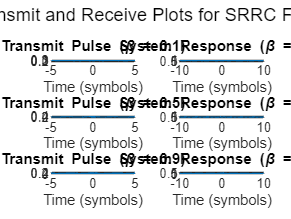

% Define parameters
roll_off_factors = [0.1, 0.5, 0.9]; % Roll-off factors (β)
oversampling_factor = 8; % Oversampling factor (samples per symbol)
filter_span = 10; % Filter span in symbols (must be integer)

% Time vector for plotting
time_vector = (-filter_span/2 : 1/oversampling_factor : filter_span/2);

% Initialize figure
figure;

% Loop through each roll-off factor
for i = 1:length(roll_off_factors)
    beta = roll_off_factors(i);

    % Design SRRC transmit and receive filters
    transmit_filter = rcosdesign(beta, filter_span, oversampling_factor, 'sqrt');
    receive_filter = transmit_filter; % Matched filtering
    
    % Convolve transmit and receive filters (equivalent system response)
    system_response = conv(transmit_filter, receive_filter, 'full');
    system_time = linspace(2 * min(time_vector), 2 * max(time_vector), length(system_response));
    
    % Plot Transmit Pulse
    subplot(length(roll_off_factors), 2, 2*i - 1);
    plot(time_vector, transmit_filter, 'LineWidth', 1.5);
    grid on;
    title(['Transmit Pulse (\beta = ', num2str(beta), ')']);
    xlabel('Time (symbols)');
    ylabel('Amplitude');
    
    % Plot System Response
    subplot(length(roll_off_factors), 2, 2*i);
    plot(system_time, system_response, 'LineWidth', 1.5);
    grid on;
    title(['System Response (\beta = ', num2str(beta), ')']);
    xlabel('Time (symbols)');
    ylabel('Amplitude');
end

% Adjust layout
sgtitle('Transmit and Receive Plots for SRRC Filter');